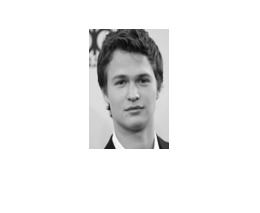

clc
clear
close all
m = 120;
n = 80;
n_images = 5;
images = zeros(m,n,n_images);
image1 = rgb2gray(imresize(imread('Fotos/ansel_elgort1.jpg'),[m,n]));
images(:,:,1) = image1;
imshow(image1);

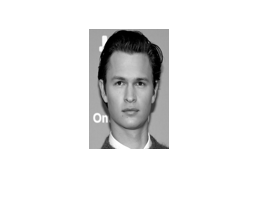

image2 = rgb2gray(imresize(imread('Fotos/ansel_elgort2.jpg'),[m,n]));
images(:,:,2) = image2;
imshow(image2);

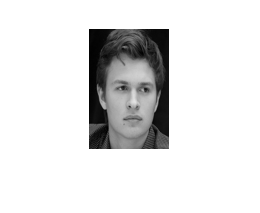

image3 = rgb2gray(imresize(imread('Fotos/ansel_elgort3.jpg'),[m,n]));
images(:,:,3) = image3;
imshow(image3);

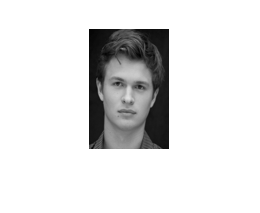

image4 = rgb2gray(imresize(imread('Fotos/ansel_elgort4.jpg'),[m,n]));
images(:,:,4) = image4;
imshow(image4);

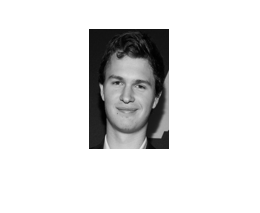

image5 = rgb2gray(imresize(imread('Fotos/ansel_elgort5.jpg'),[m,n]));
images(:,:,5) = image5;
imshow(image5);

fam1 = matriz_a(n_images, m, n, images);

A1 = transpose(fam1);

C1 = A1 * fam1;

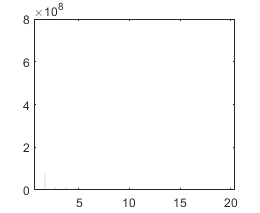

[V1,D1] = eigs(C1,20);

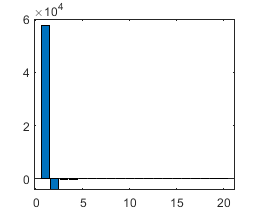

prom = 0;
for i=1:n_images
   prom = prom + images(:,:,i);
end
prom_v = reshape(transpose(prom),[1,m*n]);
p_prom = prom_v * V1;
bar(p_prom)

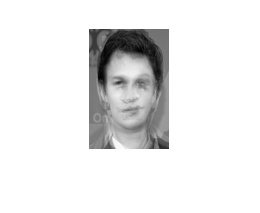

mat1 = zeros(m,n,20);
for i = 1:20
    image = transpose(reshape(V1(:,i),[n,m]));
    mat1(:,:,i) = image;
end

imshow(mat1(:,:,1),[])

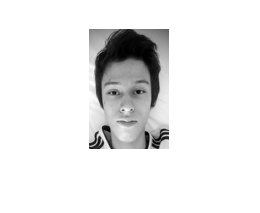

test_img = double(rgb2gray(imresize(imread('Fotos/luis.jpg'),[m,n])));
imshow(test_img,[])

test_v = reshape(transpose(test_img),[1,m*n]);

p = test_v * V1;

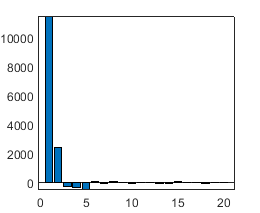

bar(p)

X = V1 * transpose(p);

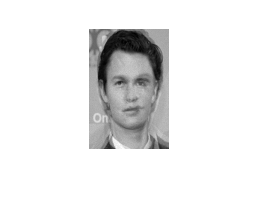

image_r = transpose(reshape(X,[n,m]));
imshow(image_r,[])

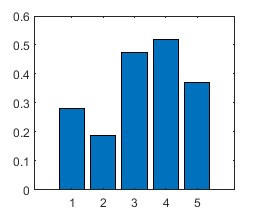

errors = calcular_error(fam1, V1, test_v);
bar(errors)

mean(errors)

ans = 0.3668